# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 4: Image Filtering, Edge Detection BW & Color

# Date: 01/26/2022

**Problem 1: Remove noise in images using various filters**								

- Download the image from ilearn (corrupted by Gaussian noise), use mean filter, median filter and Gaussian filter to remove noise and evaluate which filter works the best and why? 	

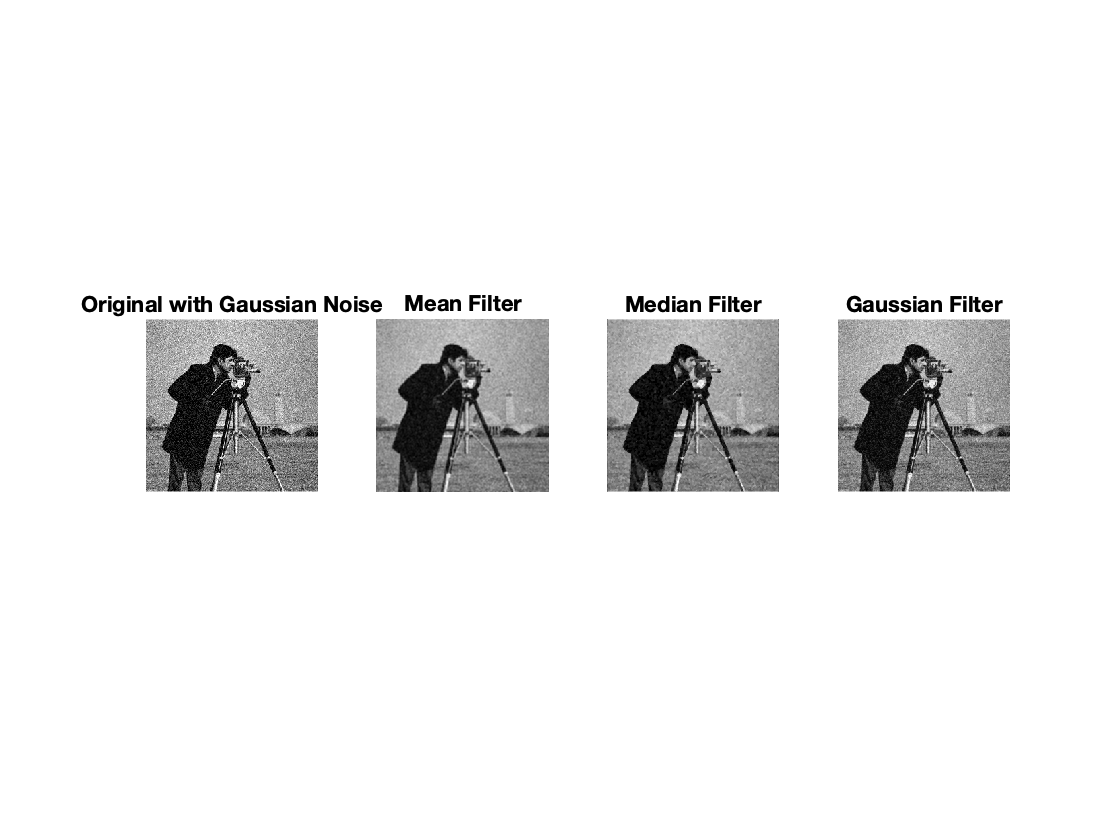

GN = imread('cameramanGN.tiff');
figure
subplot(1,4,1), imshow(GN), title("Original with Gaussian Noise");
% Use mean filter to remove noise
GN_Mean = imboxfilt(GN);
% Use median filter to remove noise
GN_Med = medfilt2(GN);
% Use Gaussian filter to remove use
GN_Gauss = imgaussfilt(GN);
subplot(1,4,2), imshow(GN_Mean), title("Mean Filter")
subplot(1,4,3), imshow(GN_Med), title("Median Filter")
subplot(1,4,4), imshow(GN_Gauss), title("Gaussian Filter")

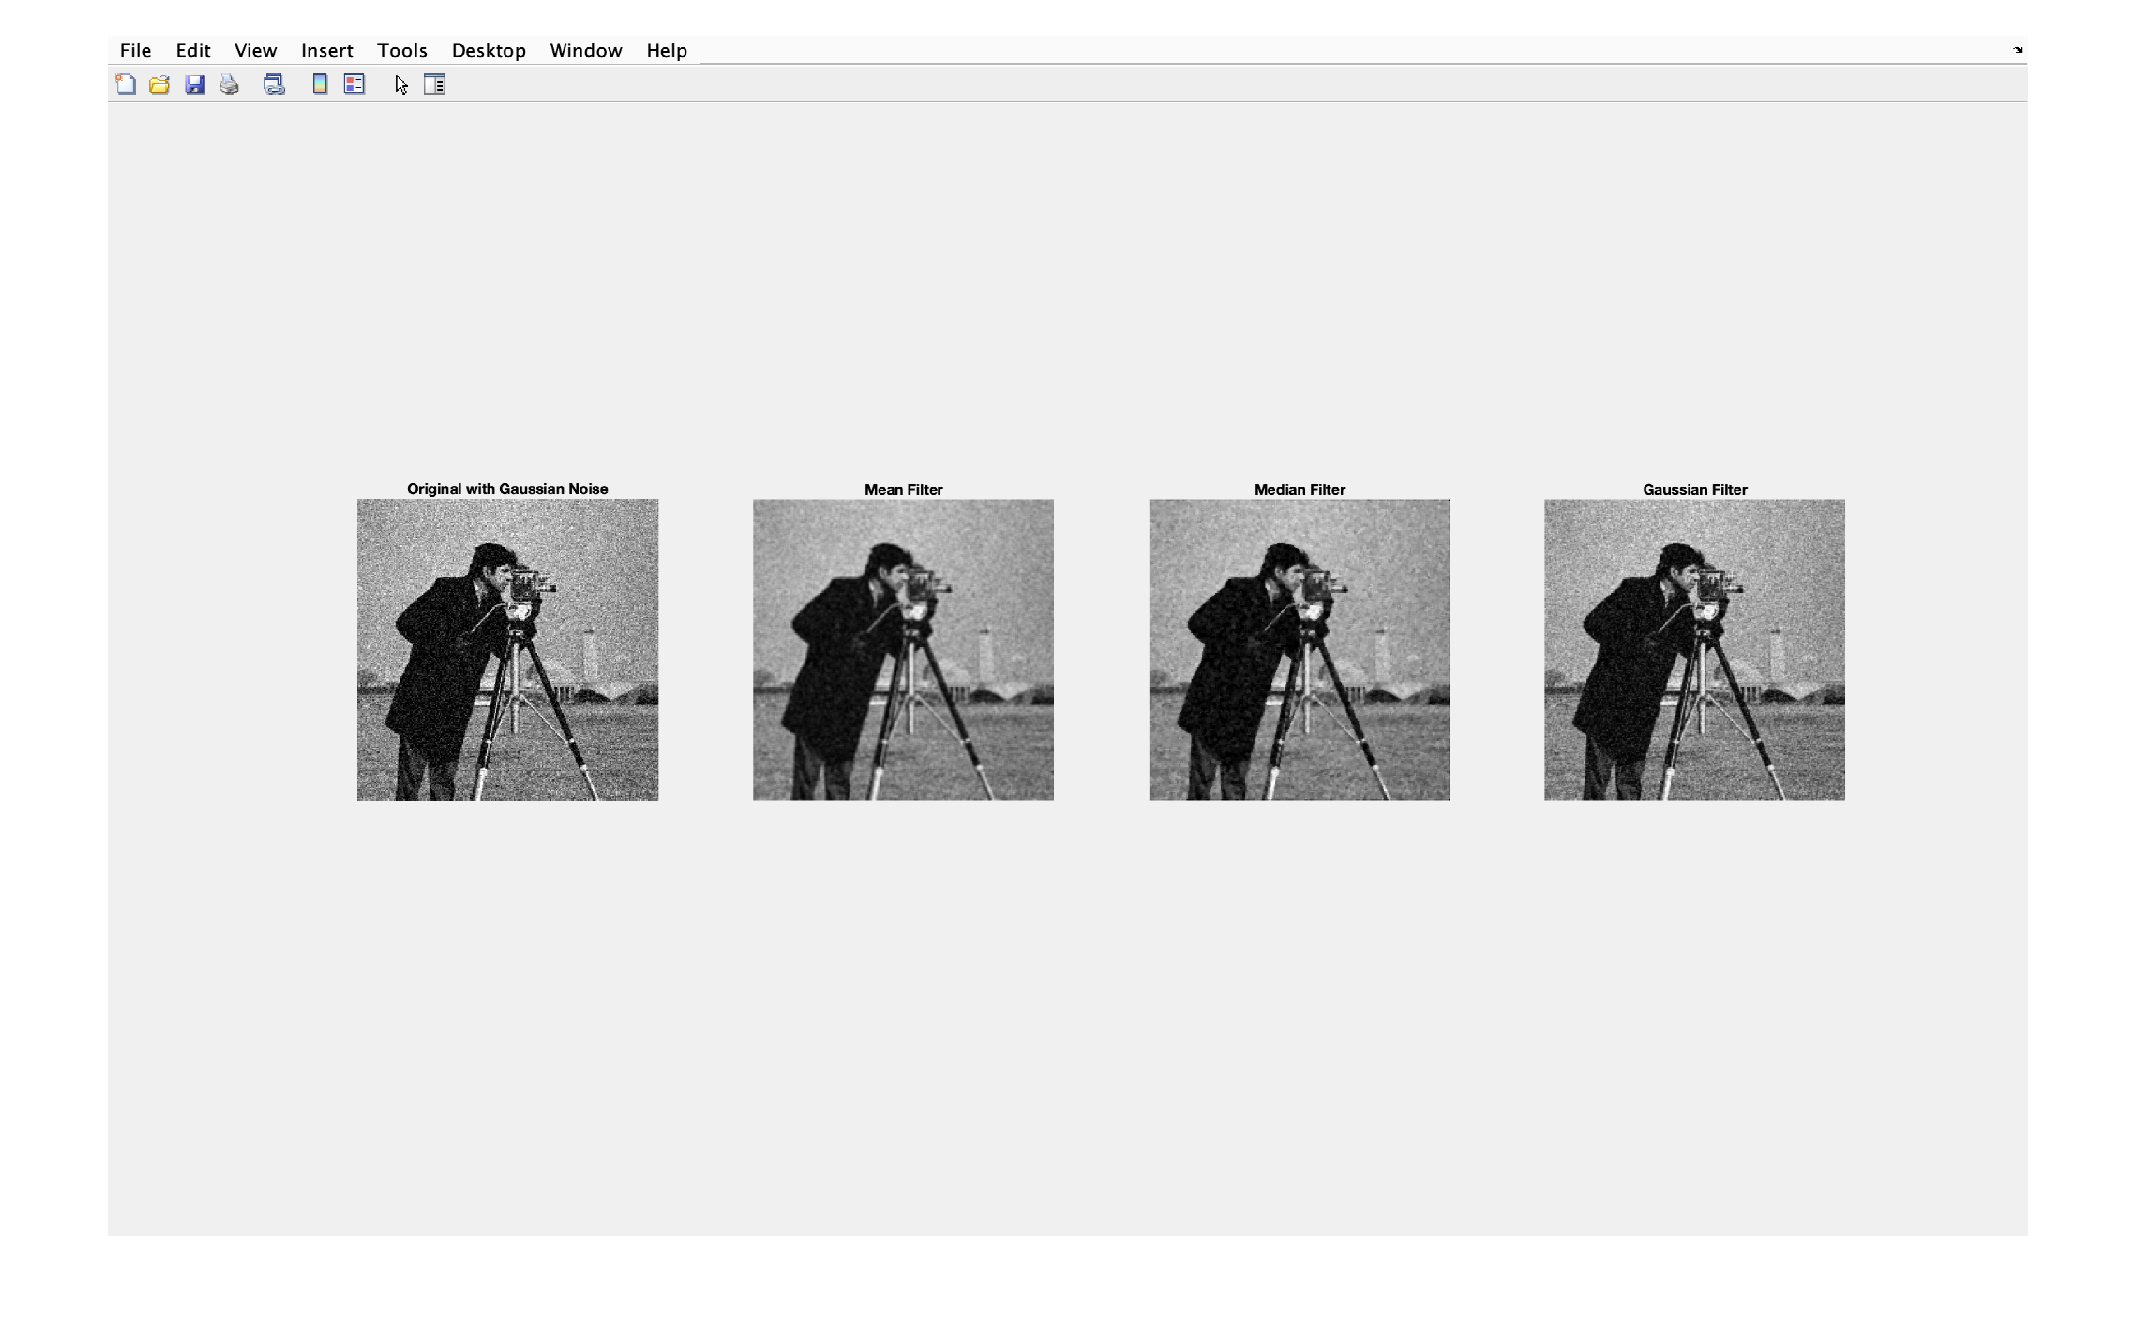

figure
imshow("Problem_1_1_Results.png")

The filter that works best is the Gaussian filter. The effect of Gaussian smoothing is to blur an image. This effect is similar to the mean filter. The degree of smoothing is determing by the standard deviation of the Gaussian. By bluring the image, the Gaussian noise is reduced

2. Download the image from ilearn (corrupted by salt and pepper noise), use mean filter, median filter and Gaussian filter to remove noise and evaluate which filter works the best and why? 

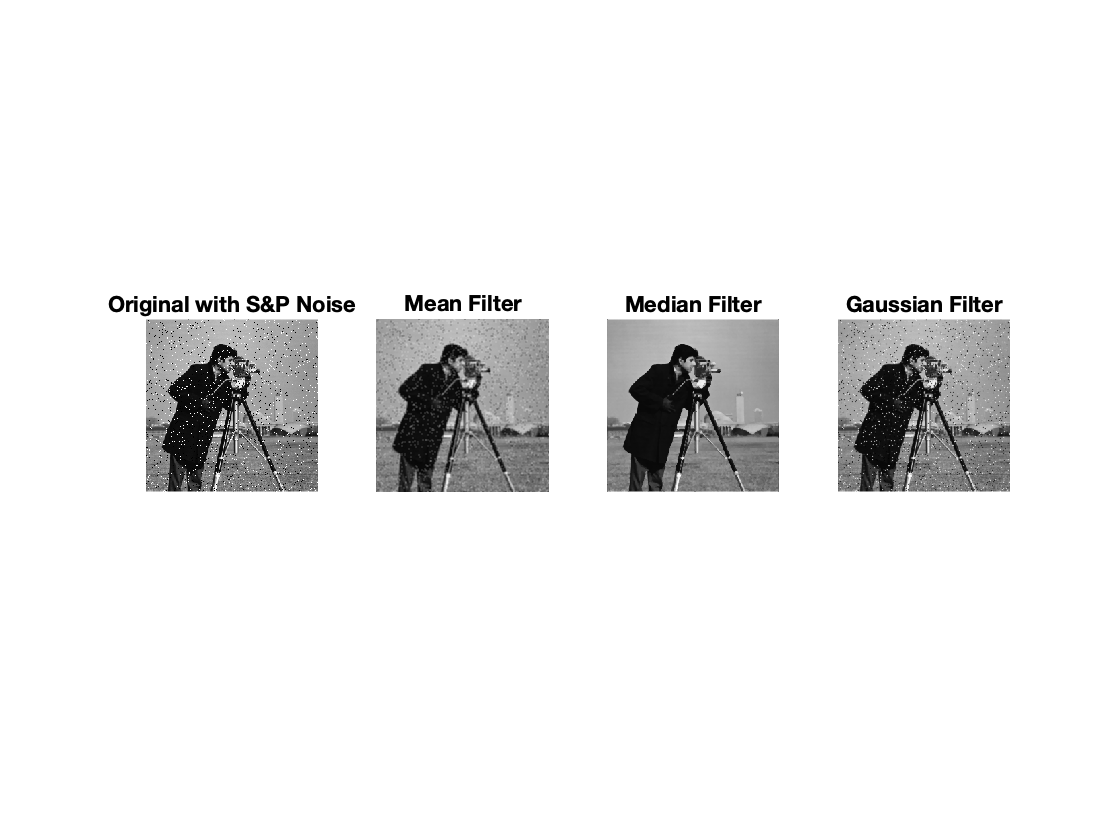

figure
SNP = imread('cameramanSPN.tiff');
subplot(1,4,1), imshow(SNP), title("Original with S&P Noise")
% Use mean filter to remove noise
SNP_Mean = imboxfilt(SNP);
% Use median filter to remove noise
SNP_Med = medfilt2(SNP);
% Use Gaussian filter to remove use
SNP_Gauss = imgaussfilt(SNP);
subplot(1,4,2), imshow(SNP_Mean), title("Mean Filter")
subplot(1,4,3), imshow(SNP_Med), title("Median Filter")
subplot(1,4,4), imshow(SNP_Gauss), title("Gaussian Filter")

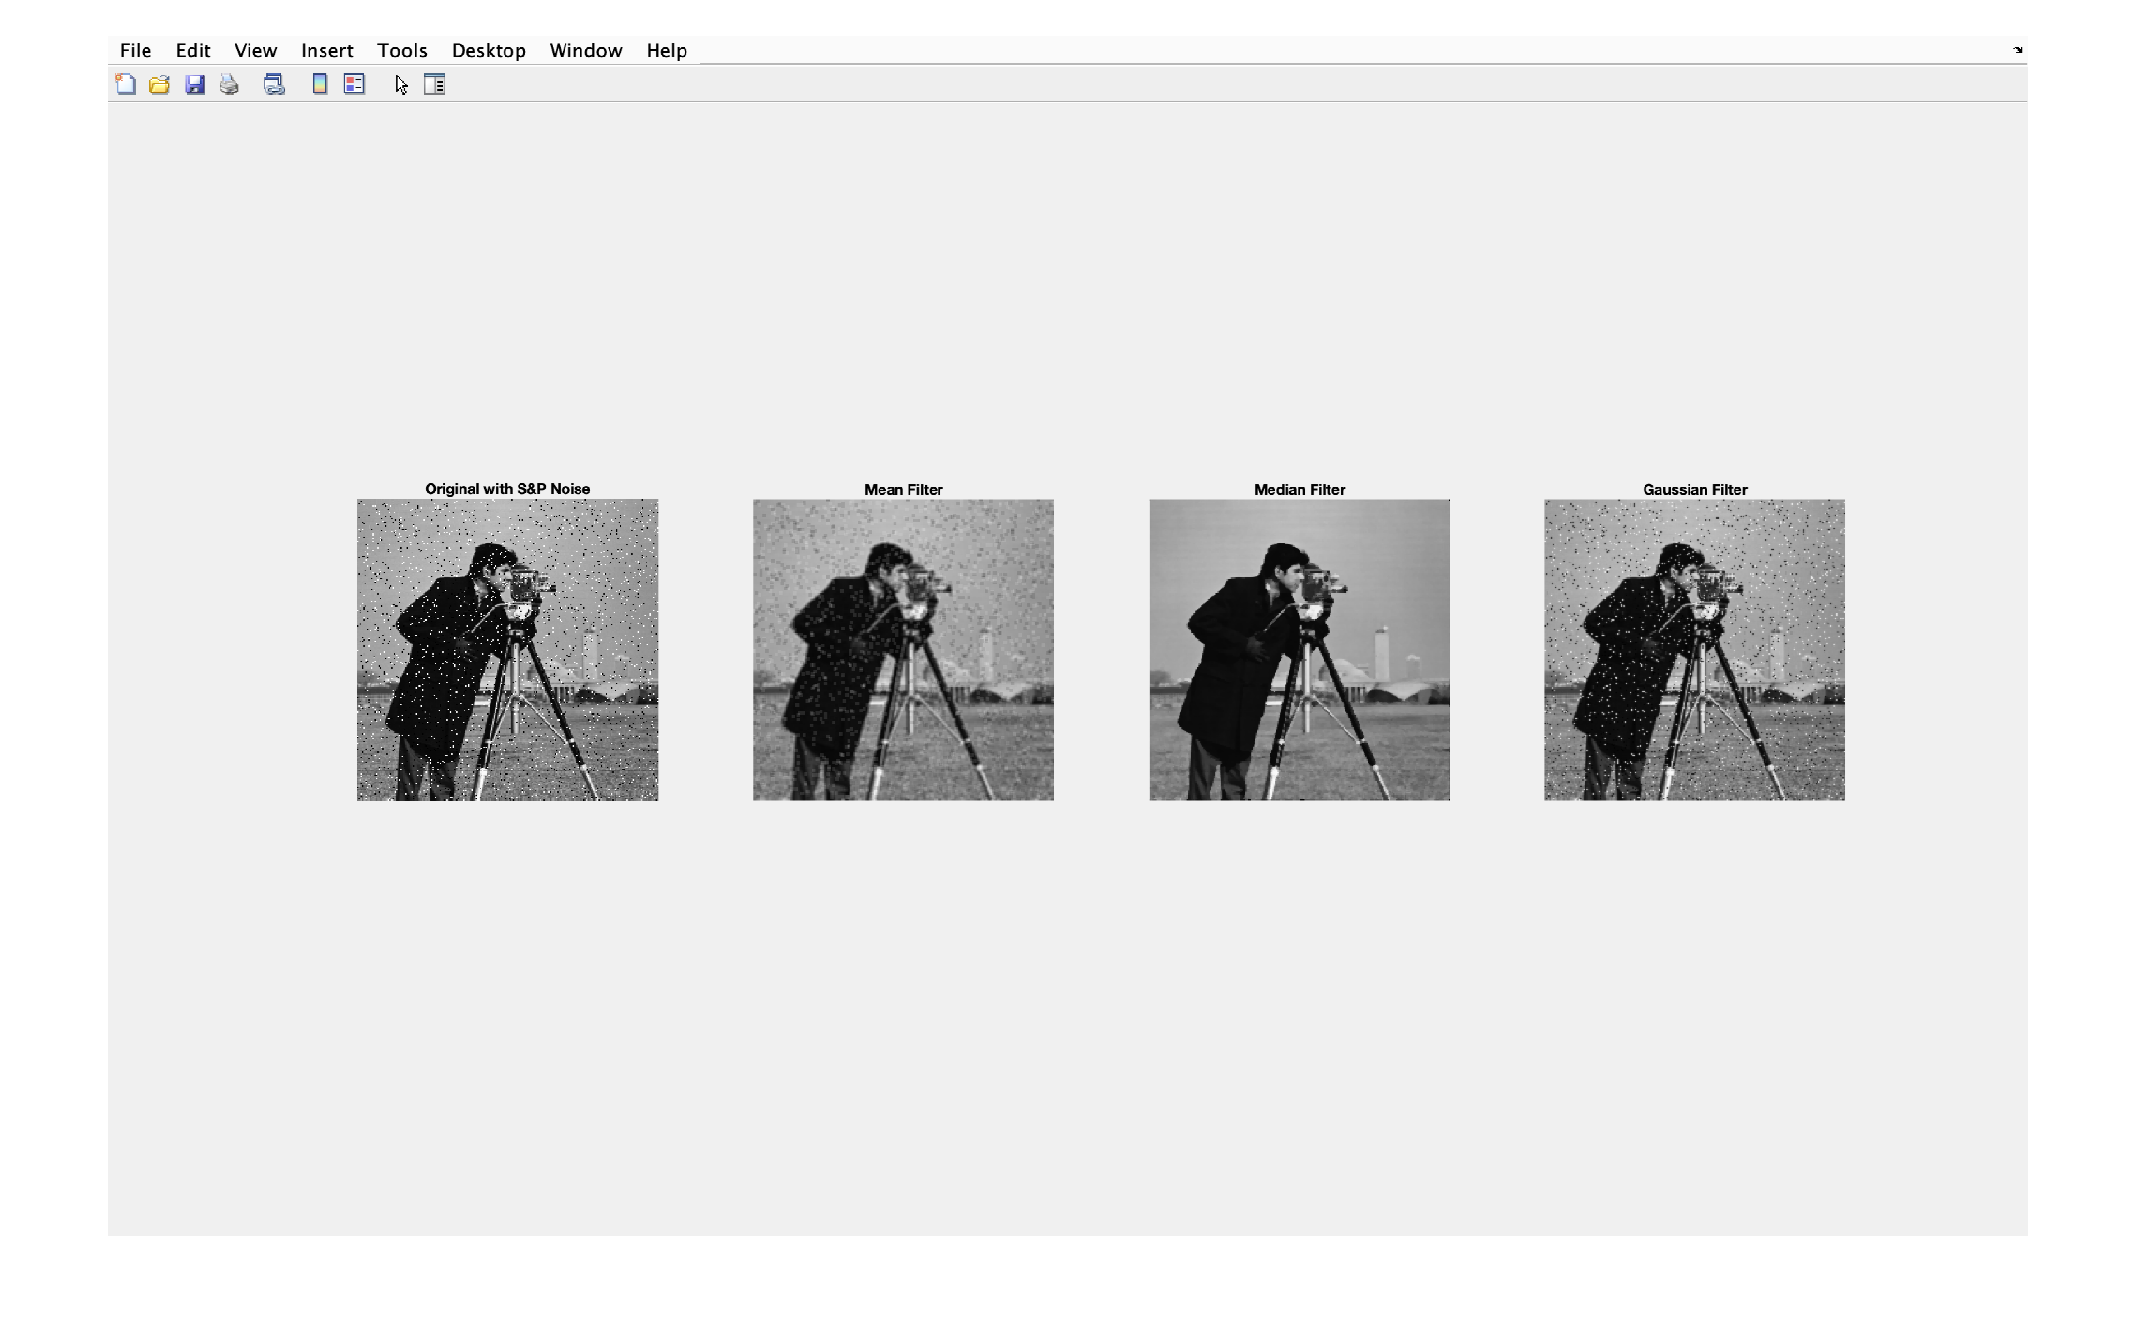

figure 
imshow("Problem_1_2_Results.png")

The median filter works best for salt and pepper because it removes the noise without damaging the original image

**Problem 2: Edge detection using different operators **

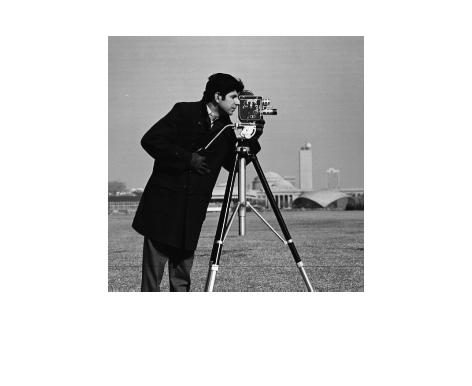

% Henry prefers that we use the built in image from Matlab instead of the
% download blur image from Matlab. Henry would like at least eight images
Blur = imread("cameraman.tif");
[counts,x] = imhist(Blur);
figure
imshow(Blur)

- Use Prewitt, Sobel, Laplacian of Gaussian (LOG, see p. 610), and Canny operators to detect the edges. Try different thresholds to detect edges and evaluate the results 

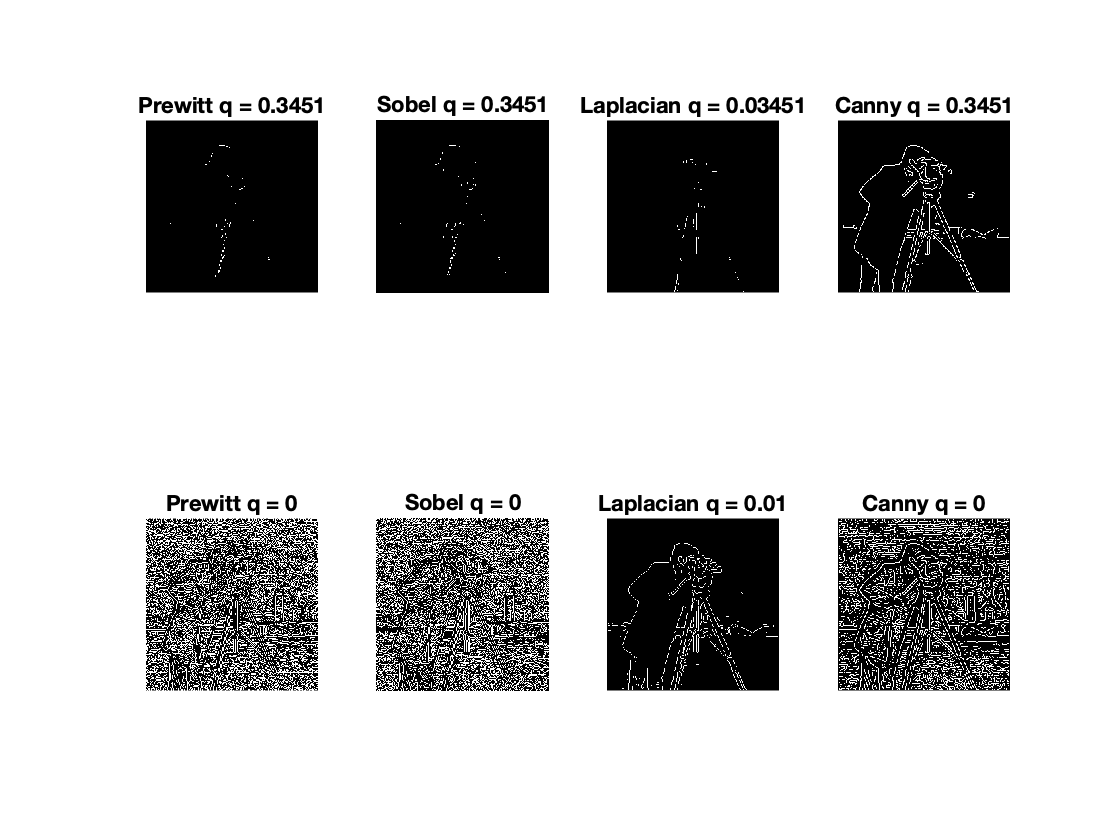

% Detect edge with Prewitt
Blur_Prewitt_Otsu = edge(Blur, "Prewitt", otsuthresh(counts));
figure
subplot(2,4,1), imshow(Blur_Prewitt_Otsu), title("Prewitt q = 0.3451")
Blur_Prewitt2_Otsu = edge(Blur, "Prewitt", 0);
subplot(2,4,5), imshow(Blur_Prewitt2_Otsu), title("Prewitt q = 0")
% Detect edge with Sobel
Blur_Sobel_Otsu = edge(Blur, "Prewitt", otsuthresh(counts));
subplot(2,4,2), imshow(Blur_Sobel_Otsu), title("Sobel q = 0.3451")
Blur_Sobel2_Otsu = edge(Blur, "Sobel", 0);
subplot(2,4,6), imshow(Blur_Sobel2_Otsu), title("Sobel q = 0")
% Detect edge with Laplacian of Gaussian
Blur_Laplacian_Otsu = edge(Blur, "Log", 0.03451);
subplot(2,4,3), imshow(Blur_Laplacian_Otsu), title("Laplacian q = 0.03451")
Blur_Laplacian2_Otsu = edge(Blur, "Log", 0.01);
subplot(2,4,7), imshow(Blur_Laplacian2_Otsu), title("Laplacian q = 0.01")
% Detect edge with Canny
Blur_Canny_Otsu = edge(Blur, "Canny", otsuthresh(counts));
subplot(2,4,4), imshow(Blur_Canny_Otsu), title("Canny q = 0.3451")
Blur_Canny2_Otsu = edge(Blur, "Canny", 0);
subplot(2,4,8), imshow(Blur_Canny2_Otsu), title("Canny q = 0")

**Problem 3: Image sharpening by Laplacian **		

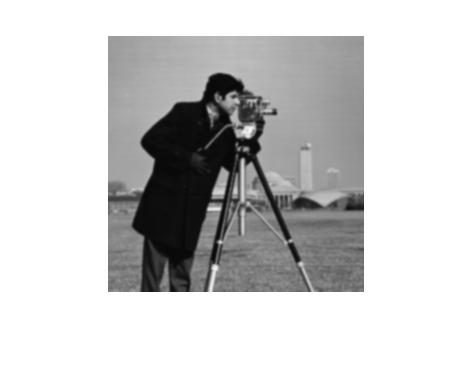

figure
blur = imread('cameramanBlur.tiff');
imshow(blur)

Sharpen the image in 1) by subtracting a weighted (weight = C) Laplacian from the blurred image. Use the function imsharpen. Try different values of parameter C. What is the effect of parameter C that you observe? 

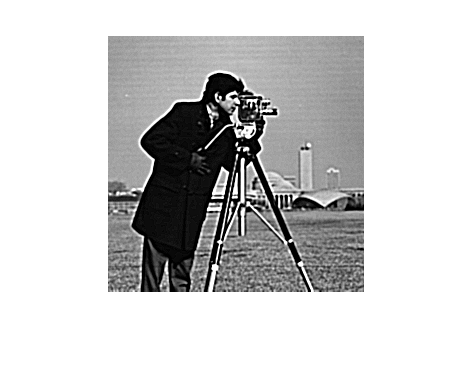

blur_sharp = imsharpen(blur, "Amount", 10);
imshow(blur_sharp)